close all; clear; clc;

# Settling Time v3 

**file name**: STv3_TM15d.mlx

**keywords:** settling time 100%

**date of test:** 20180715

**file created by:** 20180717, Edmonds

**last updated on:** 20180717

**primary purpose:** I changed the setting time to 1 instead of 0.9. All other parameters should be the same as STv1, so compare output data to that.

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:**  Forgot to measure air density. Using today's air density (0.00228603631 slugs/ft^3) for all of the data collected on 20180715. 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00228603631;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;                    % [ft]
area = pi * radius^(2);             % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv3_TM15d.mat');
time = STv3_TM15d(:,1);                       % [sec]
PWM = STv3_TM15d(:,2);                        % [micro sec]
Q = STv3_TM15d(:,4);                          % [ft.lbf]
T = STv3_TM15d(:,5);                          % [lbf]
Input_V = STv3_TM15d(:,6);                    % [Volts]
Input_A = STv3_TM15d(:,7);                    % [Amps]
rot_speed_rad = STv3_TM15d(:,8);              % [rad/sec]
% convert to RPM for plotting purposes
rot_speed_rpm = rot_speed_rad ./ (pi/30);   % [RPM]
P_in_W = STv3_TM15d(:,9);                     % [Watts]
P_out_W = STv3_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv3_TM15d(:,11);                 % [%]
Prop_Eff = STv3_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv3_TM15d(:,13);               % [lbf/Watts]  
Motor_Temp = STv3_TM15d(:,14);                % [F]


Convert the following lines to code if this is for the 90% settling time test. Delete if not applicable.

Settling_time = STv3_TM15d(:,16); % [s]
Max_Acc = STv3_TM15d(:,17);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

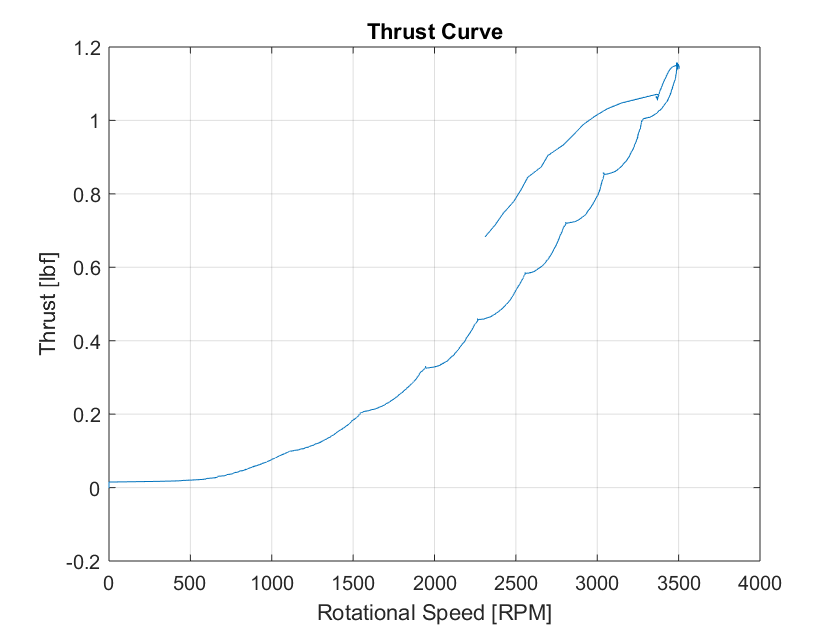

figure(1)
plot(rot_speed_rpm, T); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

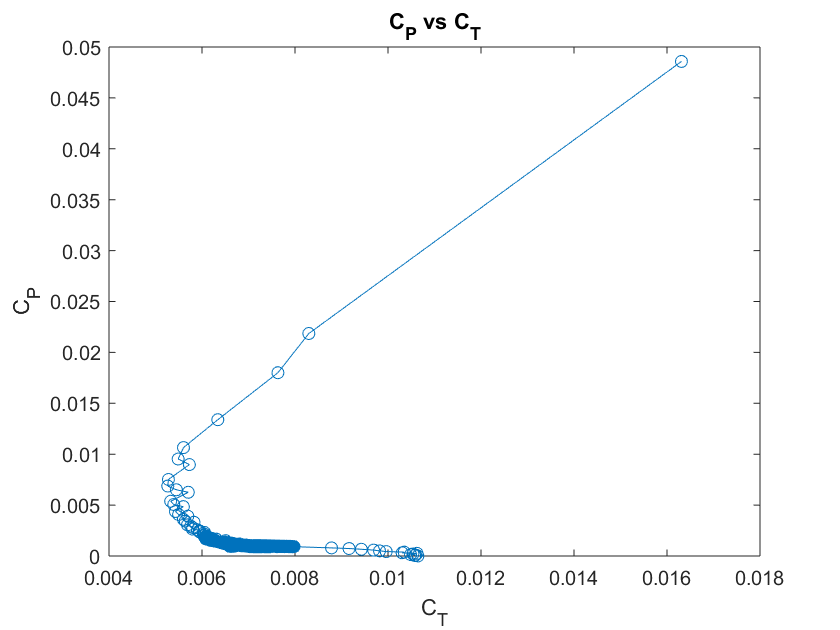


figure(2)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

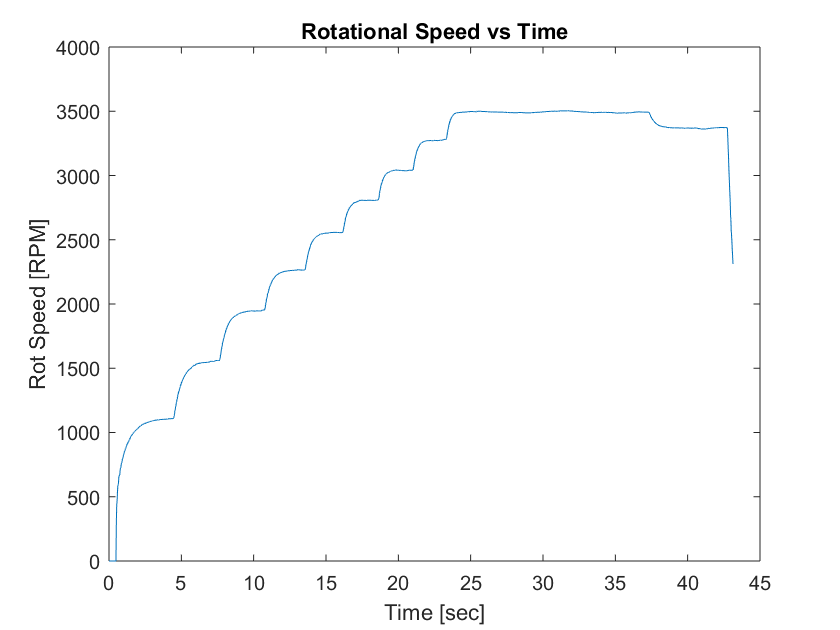


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

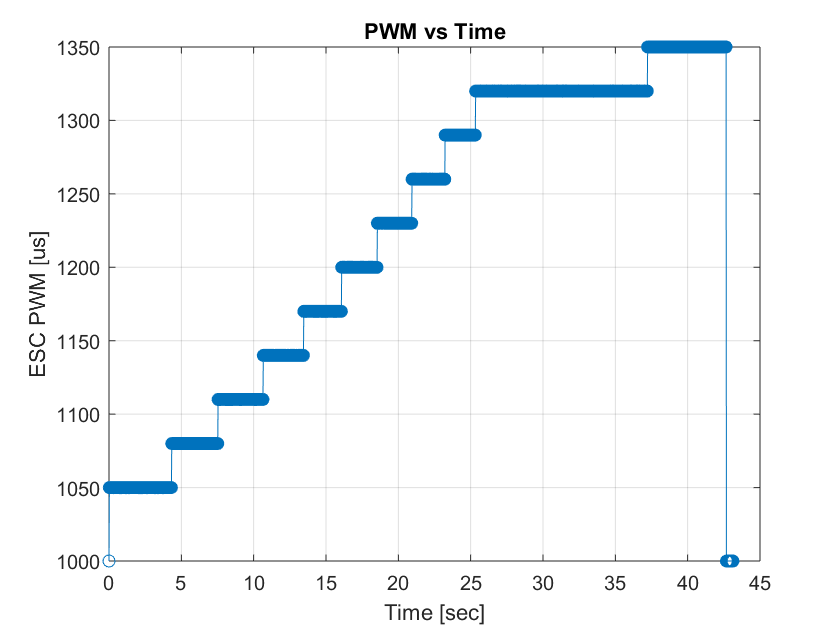


figure(4)
plot(time, PWM, 'o-'); title('PWM vs Time'); 
xlabel('Time [sec]'); ylabel('ESC PWM [us]'); grid('on');

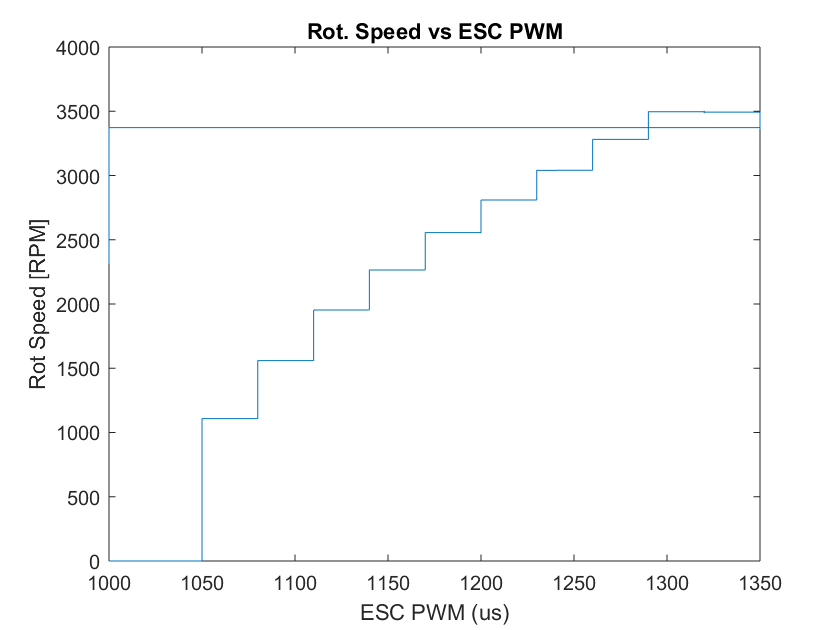


figure(5)
plot(PWM, rot_speed_rpm); title('Rot. Speed vs ESC PWM'); 
xlabel('ESC PWM (us)'); ylabel('Rot Speed [RPM]')

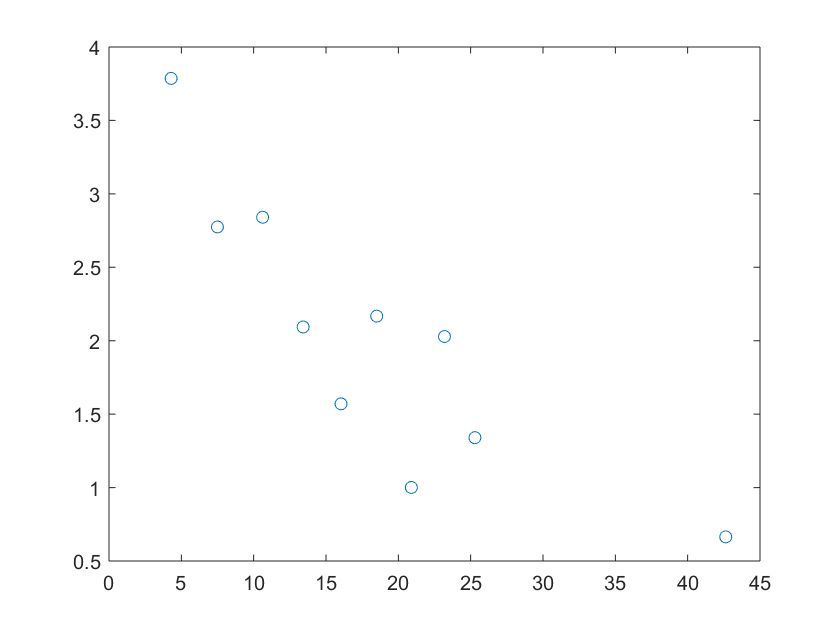


figure(6)
plot(time, Settling_time, 'o-');

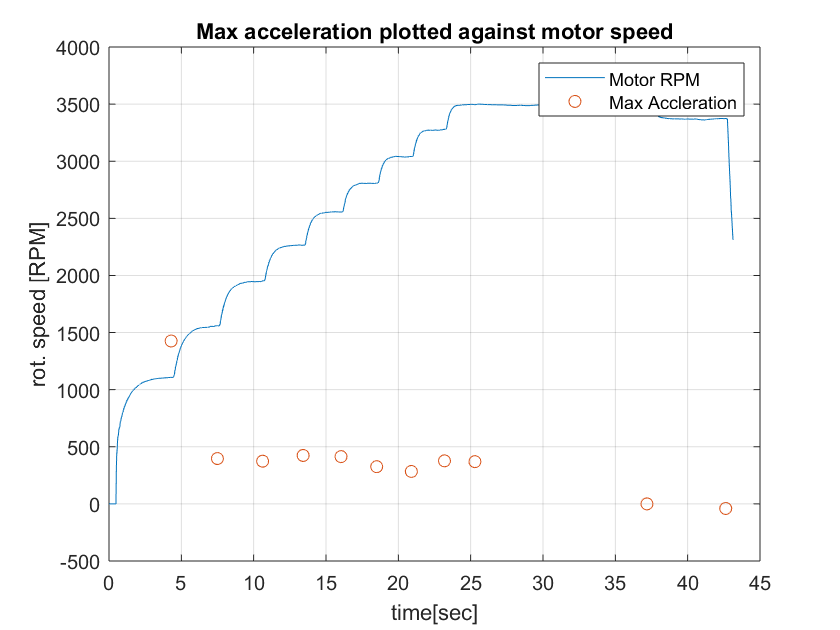


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');